# Solution series 5 - Analysis of the results of the Menchutkin experiments

## Loading the data

The readtable() routine is used to load data from a file. The routine allows different types of files (.txt, .dat, .xlsx,...). It is also possible to use the Import Data utility found in the Home menu.

data=readtable('S3/DataMenshutkin.xlsx','sheet','Menchutkin');
data.Amine=categorical(data.Amine);
disp(data)

     Amine     sigmaF    sigmaR    k10C
    _______    ______    ______    ____

    H              0         0     4390
    t-C4H9         0     -0.07     4180
    i-C3H7         0     -0.07     4060
    C2H5           0     -0.07     3950
    CH3            0     -0.08     3850
    CH2OH       0.14     -0.06     3510
    C6H5         0.1     -0.22     3350
    CH=CH2      0.06     -0.15     3260
    NH2         0.14     -0.52     2600
    NHCH3       0.12     -0.58     2520
    N(CH3)2      0.1     -0.64     2250
    OH           0.3     -0.38     2110
    CO2C2H5     0.31         0     2020
    OCH3        0.28     -0.42     1700
    Br          0.45     -0.15     1290
    Cl          0.45     -0.17     1230
    F           0.44     -0.25     1060
    CN           0.6         0     1000
    NO2         0.65         0      660



Now, let's have a graphical representation of the position of the data points in the $\sigma_F \sigma_R$ plane:

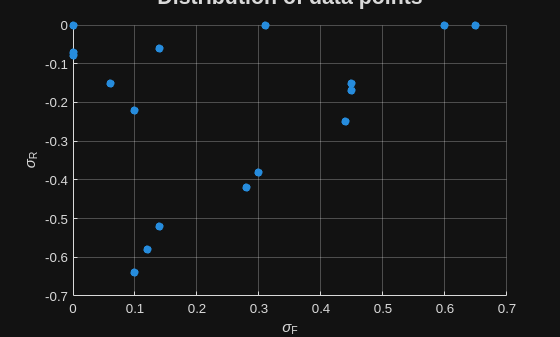

% scatter plot des points de mesure
scatter(data.sigmaF,data.sigmaR,"filled")
grid on
t=title('Distribution of data points','FontSize',16);

% Get current position of the title
pos = t.Position;

% Adjust the position (move up/down or left/right)
% Format: [x_position, y_position, z_position]
t.Position = [pos(1), pos(2) + 0.03, pos(3)]; % Moves title upward by 0.5 units

xlabel("\sigma_F")
ylabel("\sigma_R")

## Inference of the linear response model

The function fitlm() allows us to compute the fit of a linear response model  $\hat{y}=a_o + \sum a_i x_i$:

mdl_lin=fitlm(data(:,2:4),'linear');

fitlm requires Statistics and Machine Learning Toolbox.

disp(mdl_lin)

The result of the routine is made up of 3 blocks:

- The pattern identified in Wilkinson's notation

- A table with for each regressor the coefficients of the model (Estimate), the standard error (SE), the statistic t (tStat), a probability (Pvalue).

- General information about regression

In the present case, the estimates allow us to say that the regressed model is $Y=4160 - 5600 \sigma_F + 1800 \sigma_R$  if we take into account the significant figures.

The tStat is the Estimate/SE ratio and the pValue is the probability that the coefficient is zero. We can see in our case that the probabilities are minimal, far below the minimum threshold of 5%.

In the general information, you can find the level of $R^2$. The adjusted $R^2$ will allow us to make comparisons with other models that will have a number of different parameters.

### Confidence intervals of the coefficients

The coefCI() method applied to the model allows a rapid calculation of the confidence intervals. The level of confidence, which is a parameter of the function, is fixed in this case at 90%.

NiveauConfiance=0.9;
CI_lin=table(coefCI(mdl_lin,NiveauConfiance),'VariableNames',{'CI'},'RowNames',{'a_o'; 'a_1'; 'a_2'});
disp(CI_lin)

Er(1)=(CI_lin{1,1}(2)-CI_lin{1,1}(1))/(CI_lin{1,1}(2)+CI_lin{1,1}(1));
Er(2)=(CI_lin{2,1}(2)-CI_lin{2,1}(1))/(CI_lin{2,1}(2)+CI_lin{2,1}(1));
Er(3)=(CI_lin{3,1}(2)-CI_lin{3,1}(1))/(CI_lin{3,1}(2)+CI_lin{3,1}(1))

Considering the confidence intervals, it is possible to conclude that the coefficients are significant. The last claculation estimate the relative uncertainty that is less than 2%.

### ANOVA table of the linear model

SStype=2;
tbl=anova(mdl_lin,'component',SStype);
disp(tbl)

The information in the ANOVA table is consistent with previous results. The probabilities are identical. So the linear model is consistent with the experimental data provided.

### Plot of the linear model

We can use the feval() function to estimate the value of the model on points of a grid and then make a drawing of the surface.

NP=20; % nombre de points estimés
[sF,sR]=meshgrid(linspace(0,0.7,NP),linspace(-0.7,0,NP));
Yest=feval(mdl_lin,sF,sR);

surf(sF,sR,Yest)
hold on
plot3(data.sigmaF,data.sigmaR,data.k10C,'ok','MarkerSize',10,'MarkerFaceColor','red')
hold off


set(gca,'FontSize',14)
title('Plot of the linear model')
xlabel('\sigma_F')
ylabel('\sigma_R')
view(-36,60)

We observe that the points are close to the model. For a more correct representation, it is necessary to give up representing the model in the zone which does not have measurement. As was done in the previous series, we will determine a straight line which represents the boundary of the domain. The coefficients $\alpha$ of this line are obtained by the calculation $\alpha=A^{-1}R$ if $A$ is the matrix of the model corresponding to the line which passes through the points (0.1,-0.7) and (0.7,0):

A=[1 0.1;1 0.7];
disp(A)

and $R$ the values corresponding to $x_2$

R=[-0.7;0];
disp(R)

So the coefficient of the line are:

alpha=A\R;
format rat
disp(alpha)
format short

Then it is ne cessary to put a value *nan* for all the excluded points.

k=find(5-7*sF+6*sR<0);
Yest(k)=nan;
surf(sF,sR,Yest)

hold on
plot3(data.sigmaF,data.sigmaR,data.k10C,'ok','MarkerSize',10,'MarkerFaceColor','red')
hold off

set(gca,'FontSize',14)
title('Plot of the linear model')
xlabel('\sigma_F')
ylabel('\sigma_R')
view(-36,60)

We can also set the viewing angle tangent to the model and observe the distribution of the measurement points on either side of the plane representing the linear model:

surf(sF,sR,Yest)

hold on
plot3(data.sigmaF,data.sigmaR,data.k10C,'ok','MarkerSize',10,'MarkerFaceColor','red')
hold off

set(gca,'FontSize',14)
title('Plot of the linear model')
xlabel('\sigma_F')
ylabel('\sigma_R')

view([-96 43])

You can get something similar with the function *plotAdded() *:

plotAdded(mdl_lin)

### Results for a standardized design

Finally, let's look at the results obtained with the fitlm() function for a standardized plan.

E=data{:,["sigmaF","sigmaR"]};
E_st=rescale(E,-1,1,"InputMin",min(E),"InputMax",max(E));
mdl_lin_st=fitlm(E_st,data{:,"k10C"},'linear');
disp(mdl_lin_st)

The coefficients are of course different. On the other hand, the ANOVA table remains the same since it is a question of attributing the variance of the response to the different factors:

tbl_st=anova(mdl_lin_st,'component',SStype);
disp(tbl_st)

## Inference of the linear model with interactions

Now let's look at the results of projecting the data onto a linear model with interaction

 $y=a_o+a_1x_1+a_2x_2+a_{12}x_1x_2$.

mdl_int=fitlm(data(:,2:4),'interactions');
disp(mdl_int)

### Confidence intervals of the coefficients

CI_int=table(coefCI(mdl_int),'VariableNames',{'CI'},...
    'RowNames',{'a_o'; 'a_1'; 'a_2';'a_{12}'});
disp(CI_int)

We can observe that the CI have increased significantly and for the interaction it cross the zero line.

### ANOVA table for the linear model with interactions

The ANOVA table for the model with interaction shows that the addition of an interaction term is not justified in statistical terms since the probability that this term is zero is 82%.

tbl=anova(mdl_int,'component',2);
disp(tbl)

### Dotplot of the effects

We can also observe that at the level of the confidence intervals the situation is significantly worse than the situation with only main effects.

figure
errorbar(1:4,mdl_int.Coefficients.Estimate,...
    mdl_int.Coefficients.Estimate-CI_int.CI(:,1),'or')
grid on
title('Confidence intervals of the coefficients')
axis([.5,4.5,-7000,7000])
set(gca,'XTick',1:4,'XTickLabel',{'a_o' 'a_1' 'a_2' 'a_{12}'},...
    'FontSize',14)
hold on
plot([.5,4.5],[0, 0],'LineWidth',2)
hold off

### Plot of the linear model with interaction

The function plot illustrates that the interaction term adds absolutely nothing to the model. The curvature created by the interaction term is quite imperceptible. However, it is important to specify that this is only valid for the area in which the measurement points are placed.

Yest=feval(mdl_int,sF,sR);
Yest(k)=nan;
surf(sF,sR,Yest)

hold on
plot3(data.sigmaF,data.sigmaR,data.k10C,'ok','MarkerSize',10,'MarkerFaceColor','red')
hold off

set(gca,'FontSize',14)
title('Plot of the model')
xlabel('\sigma_F')
ylabel('\sigma_R')
view(-36,60)


## Inference of the quadratic model

Now let's look at the results of projecting the data onto a quadratic model

$y=a_o+a_1x_1+a_2x_2+a_{12}x_1x_2+a_{11}x_1^2+a_{22}x_2^2$.

mdl_quad=fitlm(data(:,2:4),'quadratic');
CI_quad=table(coefCI(mdl_quad),'VariableNames',{'CI'},'RowNames',...
    {'a_o'; 'a_1'; 'a_2';'a_{12}';'a_{11}';'a_{22}'});disp(CI_quad)

We observe that the CI have increased again significantly and that for the interaction and quadratic coefficients the CI cross the zero line.

### ANOVA table for the quadratic model

tbl=anova(mdl_quad,'component',2);
disp(tbl)

Let's observe the huge p-values for all but one coefficients.

### Dotplot of the effects

figure
errorbar(1:6,mdl_quad.Coefficients.Estimate,...
    mdl_quad.Coefficients.Estimate-CI_quad.CI(:,1),'or')
grid on
title('Confidence intervals of the coefficients')
axis([.5,6.5,-10000,10000])
set(gca,'XTick',1:6.5,'XTickLabel',{'a_o'; 'a_1'; 'a_2';'a_{12}';'a_{11}';'a_{22}'},...
    'FontSize',14)
hold on
plot([.5,6.5],[0, 0],'LineWidth',2)
hold off

### Plot of the quadratic model

Yest=feval(mdl_quad,sF,sR);
Yest(k)=nan;
surf(sF,sR,Yest)

hold on
plot3(data.sigmaF,data.sigmaR,data.k10C,'ok','MarkerSize',10,'MarkerFaceColor','red')
hold off

set(gca,'FontSize',14)
title('Plot of the quadratic model')
xlabel('\sigma_F')
ylabel('\sigma_R')
view([-11 -4])

All the available indicators show that the quadratic model does not make sense in this situation since it definitely ruins the confidence of all the coefficients except for the constant and the main effect of the first factor. The model is however not faulty and on the figure above one can see that the introduction of a curvature of the segond degree is not contrary to the data, but that does not bring anything in terms of prediction and according to the principle of parsimony it is preferable to be satisfied with the linear model.

These analyzes after the experiments confirm the analysis of the plan made a priori. Indeed, during the analysis of the design in the previous series, this result had already been predicted by the indicators which already showed the insufficiency of the measurement points to correctly identify the second degree terms.